# Function for Presentation: BrainRed

clc; clear all; close all;
CurrentDirectory = uigetdir;
DirectoryFiles = dir(fullfile(CurrentDirectory,'*.mat'));
for k = 1:length(DirectoryFiles)
  FileName = DirectoryFiles(k).name;
  FileNameExtension = fullfile(CurrentDirectory, FileName);
  CurrentFile = importdata(FileNameExtension);
  load(FileName);
  tumorImage = cjdata.image;
  ImageConvert = mat2gray(tumorImage);
  imwrite(ImageConvert, [extractBefore(FileName, "."), '_', int2str(cjdata.label), '.png']);
end

Loads all the .mat files from the data set, isolates the images, and saves them into Testing and Training folders..

A = imageDatastore('Final Project Images\Training\Group1\');
M = datastore('Final Project Images\Training\Group2\');
PT = datastore('Final Project Images\Training\Group3\');

Creates 3 image datastores for the 3 types of tumor.

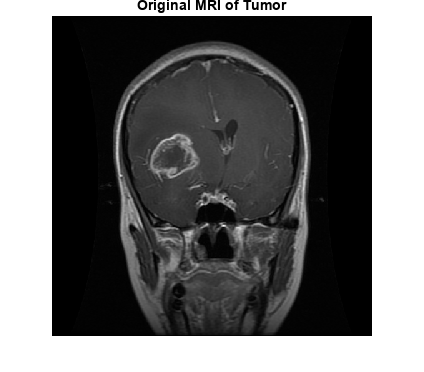

TestImage = readimage(A,15);
imshow(TestImage);
title('Original MRI of Tumor');

Initializes a test image for the purposes of the demonstration

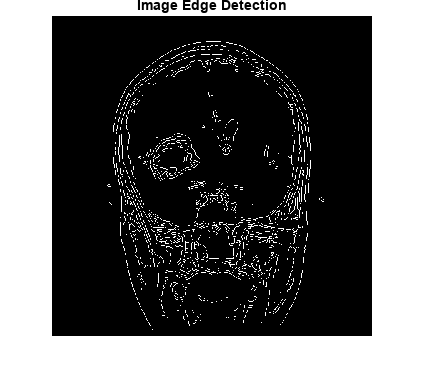

TestImage = im2gray(TestImage);
TestImage = imadjust(TestImage);
[~,Thresh] = edge(TestImage,'sobel');
FudgeFactor= 0.75;
ImageEdge = edge(TestImage,'sobel',FudgeFactor*Thresh);
imshow(ImageEdge)
title('Image Edge Detection');

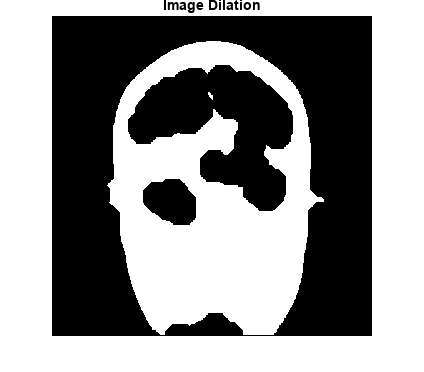

SE = strel('disk', round(length(TestImage)/22));
ImageDialation = imclose(ImageEdge,SE);
imshow(ImageDialation);
title('Image Dilation');

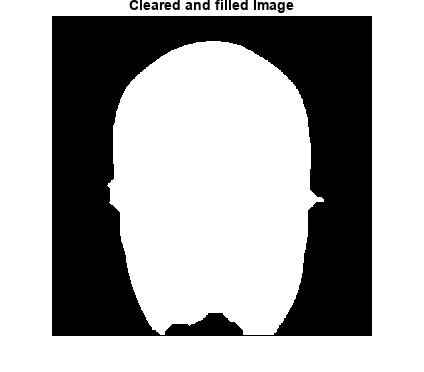

FilledImage = imfill(ImageDialation, 'holes');
ImageClear = imclearborder(FilledImage, 4);
imshow(ImageClear);
title('Cleared and filled Image');

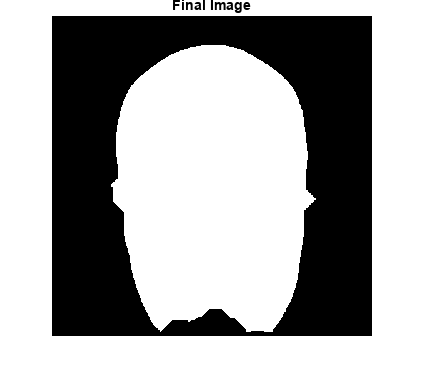

SEd = strel('diamond', 3);
ImageFinal = imerode(ImageClear,SEd);
ImageFinal = imerode(ImageFinal, SEd);
imshow(ImageFinal);
title("Final Image");